## **1构建数据**

 for m = 1:18
     patchdata{1,m} = zeros(89,96,81);
     for i = 1:12
       
        patchdata{1,m} = patchdata{1,m}+All_data_prepatch{i,m}(1:89,:,:);
    end
end

load('/home/dclab2/Ensemble coding/data/SNR.mat')
% 选择前 30 个线圈
[~, coilidx] = sort(coilSNR, 'descend');
coilselect = coilidx(1:30);
All_data  = {All_data_preEC,All_data_preEC0,All_data_preSC,All_data_prepatch,patchdata};


clear All_data_preEC All_data_preEC0 All_data_preSC All_data_prepatch
ori = [1, 9]; % 两种取向条件
data = cell(2, 3); % 初始化存储结果的 cell

% 遍历条件和两种ori
for condition = 1:5
    for i = 1:2
        % 提取所有 trial 的数据，保留对应的线圈 (coilselect)
        alldata_condition_ori = All_data{condition}{1, ori(i)};
        alldata_selected_coil = alldata_condition_ori(:, coilselect, :); % 取出选定的线圈

        % 对所有 trial 和选定的线圈进行滑动平均
        datapre = movmean(alldata_selected_coil, 5, 3); % 第3维（时间点）进行滑动平均
%         min_data = min(datapre(:)); % 沿着第一个维度计算均值，结果为 (1, 30, 81)
%         max_data = max(datapre(:)); % 沿着第一个维度计算标准差，结果为 (1, 30, 81)
% 
%         % Z-score 标准化
%         z_score_data = (datapre - min_data) ./ (max_data-min_data); % 直接进行标准化
        data{i,condition} = datapre;

    end
end


## 2.构建Patch的tunng

for ori = 1:18
    patch_ec0{1,ori} = squeeze(mean(patchdata{1,ori}(1:89,:,:)-All_data_preEC0{1,ori}(1:89,1:96,:),1));
    for coil = 1:96
        patch_ec0_tuning(:,coil,ori) = patch_ec0{1,ori}(coil,:);
        patch_tuning(:,coil,ori) = squeeze(mean(patchdata{1,ori}(:,coil,:),1));
        EC0_tuning(:,coil,ori) = squeeze(mean(All_data_preEC0{1,ori}(:,coil,:),1));
    end
end

figure;
load('/home/dclab2/Ensemble coding/data/chanmap.mat');
for coil = 1:96
    n = find(ChanMap==coil);
    subplot(10,10,n)
    hold on
    datapp = mean(patch_tuning(40:45,coil,:),1)/12;
    plot(smooth(squeeze(datapp-min(datapp))));
%     datapp = mean(patch_ec0_tuning(40:55,coil,:),1);
%     plot(smooth(normalize(squeeze(datapp-min(datapp)))),'LineWidth',1.5);
    datapp = mean(EC0_tuning(40:45,coil,:),1);
    plot(smooth(squeeze(datapp-min(datapp))));
    hold off
    subtitle(sprintf('coil-%d',coil));
    
end
sgtitle('Tuning of Orientation')
legend('PATCH','PATCH-EC0','EC0');
subplot(10,10,1);
xlabel('orientation');
ylabel('Response-min(Rsesponse)');

## 3.PCA

%在这之前，先完成信号的信噪比对齐

cond1 = All_data{1,2}{1,1}(1:89,coilselect,:);
cond2 = All_data{1,2}{1,9}(1:89,coilselect,:);
cond3 = All_data{1,5}{1,1}(1:89,coilselect,:);
cond4 = All_data{1,5}{1,9}(1:89,coilselect,:);
data_all = cat(1,cond1, ...
    cond2, ...
    cond3, ...
    cond4);
% 展平每个trial为 (neuron*time) 特征向量
[n_trials, n_neurons, n_times] = size(data_all);
data_flat = reshape(data_all, n_trials, n_neurons * n_times); % 356x2430
% 分组：朝向10° (cond1 + cond3) 和朝向90° (cond2 + cond4)
group_orient_10 = [cond1; cond3]; % 178x30x81
group_orient_90 = [cond2; cond4]; % 178x30x81

% 计算每个神经元在每个时间点的均值响应
mean_10 = squeeze(mean(group_orient_10, 1)); % 30x81
mean_90 = squeeze(mean(group_orient_90, 1)); % 30x81

% 计算朝向引发的方差 (按神经元和时间点)
var_orient = mean((mean_10(:) - mean_90(:)).^2);

% 计算总方差
total_var = mean(data_flat(:).^2) - (mean(data_flat(:))^2); % 或使用 var(data_flat(:),1)

% 相对方差贡献
relative_var_orient = (var_orient / total_var) * 100;
% 分组：有整体 (cond1 + cond2) 和无整体 (cond3 + cond4)
group_global_yes = [cond1; cond2]; % 178x30x81
group_global_no = [cond3; cond4]; % 178x30x81

% 计算均值响应
mean_yes = squeeze(mean(group_global_yes, 1)); % 30x81
mean_no = squeeze(mean(group_global_no, 1)); % 30x81

% 计算整体引发的方差
var_global = mean((mean_yes(:) - mean_no(:)).^2);

% 相对方差贡献
relative_var_global = (var_global / total_var) * 100;
% 执行PCA
[coeff, score, latent, ~, explained] = pca(data_flat); % coeff: 2430x2430, score: 356x2430

% 提取前k个主成分（例如前50个）
k = 355;
score_k = score(:, 1:k); % 356x50
coeff_k = coeff(:, 1:k); % 2430x50

% 设计任务变量标签
% 朝向标签: 1=10°, 0=90°
orient_labels = [ones(89,1); zeros(89,1);ones(89,1); zeros(89,1)]; % 356x1
% 整体标签: 1=有整体, 0=无整体
global_labels = [ones(178,1); zeros(178,1)]; % 356x1

% 计算每个PC中任务变量的信号方差
signal_var_orient = zeros(k, 1);
signal_var_global = zeros(k, 1);

for i = 1:k
    % 朝向变量回归模型
    mdl_orient = fitlm(score_k(:,i), orient_labels); % 注意输入顺序：X=PC得分, Y=标签
    signal_var_orient(i) = mdl_orient.Rsquared.Ordinary * var(score_k(:,i));
    
    % 整体变量回归模型
    mdl_global = fitlm(score_k(:,i), global_labels);
    signal_var_global(i) = mdl_global.Rsquared.Ordinary * var(score_k(:,i));
end

% 累积信号方差
cum_signal_orient = cumsum(signal_var_orient);
cum_signal_global = cumsum(signal_var_global);

% 总方差由前k个PCs解释
total_var_pcs = sum(latent(1:k)); % 或 sum(var(score_k))

% 相对累积贡献
relative_cum_orient = (cum_signal_orient / total_var_pcs) * 100;
relative_cum_global = (cum_signal_global / total_var_pcs) * 100;
% 生成随机正交矩阵
% 方法1：在每个neuron-time上随机打乱trial
data_random = zeros(size(data_flat));
for i = 1:size(data_flat,2)
    data_random(:,i) = data_flat(randperm(size(data_flat,1)), i);
end
% 对随机数据执行PCA
[~, score_rand, latent_rand] = pca(data_random);
score_rand_k = score_rand(:, 1:k);

% 计算随机基的信号方差（方法同上）
signal_var_rand_orient = zeros(k, 1);
signal_var_rand_global = zeros(k, 1);

for i = 1:k
    mdl_rand_orient = fitlm(score_rand_k(:,i), orient_labels);
    signal_var_rand_orient(i) = mdl_rand_orient.Rsquared.Ordinary * var(score_rand_k(:,i));
    
    mdl_rand_global = fitlm(score_rand_k(:,i), global_labels);
    signal_var_rand_global(i) = mdl_rand_global.Rsquared.Ordinary * var(score_rand_k(:,i));
end

% 累积信号方差和相对贡献
cum_signal_rand_orient = cumsum(signal_var_rand_orient);
cum_signal_rand_global = cumsum(signal_var_rand_global);

total_var_rand_pcs = sum(latent_rand(1:k));
relative_cum_rand_orient = (cum_signal_rand_orient / total_var_rand_pcs) * 100;
relative_cum_rand_global = (cum_signal_rand_global / total_var_rand_pcs) * 100;
% 绘制朝向变量的累积贡献
figure;
plot(1:k, relative_cum_orient, 'b-', 'LineWidth', 2);
hold on;
plot(1:k, relative_cum_rand_orient, 'r--', 'LineWidth', 2);
xlabel('Number of PCs');
ylabel('Relative Cumulative Signal Variance (%)');
title('Orientation Contribution vs Random Basis');
legend('Orientation Contribution', 'Random Basis');
grid on;

% 绘制整体变量的累积贡献
figure;
plot(1:k, relative_cum_global, 'g-', 'LineWidth', 2);
hold on;
plot(1:k, relative_cum_rand_global, 'm--', 'LineWidth', 2);
xlabel('Number of PCs');
ylabel('Relative Cumulative Signal Variance (%)');
title('Global Context Contribution vs Random Basis');
legend('Global Context', 'Random Basis');
grid on;

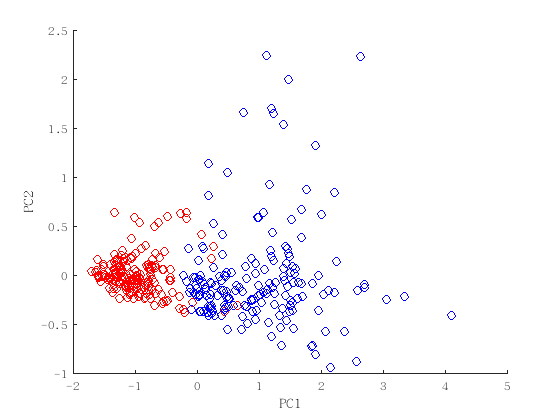

cond1 = All_data{1,2}{1,1}(1:89,coilselect,:);
cond2 = All_data{1,2}{1,9}(1:89,coilselect,:);
cond3 = All_data{1,5}{1,1}(1:89,coilselect,:);
cond4 = All_data{1,5}{1,9}(1:89,coilselect,:);
cond1 = (cond1 -min(cond1(:)))/(max(cond1(:))-min(cond1(:)));
cond2 = (cond2 -min(cond2(:)))/(max(cond2(:))-min(cond2(:)));
cond3 = (cond3 -min(cond3(:)))/(max(cond3(:))-min(cond3(:)));
cond4 = (cond4 -min(cond4(:)))/(max(cond4(:))-min(cond4(:)));
% 步骤1：数据整合与预处理
data_all = cat(1, cond1, cond2, cond3, cond4);
labels_global = [ones(178, 1); zeros(178, 1)];
labels_orientation = [ones(89, 1); zeros(89, 1);ones(89, 1); zeros(89, 1)];
data_normalized = zscore(data_all, 0, 1);

% 步骤2：时间窗口划分（示例窗口）
window_size = 50;
current_data = squeeze(mean(data_normalized(:,:,1:50), 3));

% 步骤3：PCA
[coeff, score, latent] = pca(current_data);

% 步骤4：变量方差计算
group_10 = score(labels_orientation == 1, 1:3);
group_90 = score(labels_orientation == 0, 1:3);
var_orientation = sum((mean(group_10) - mean(group_90)).^2);

group_global = score(labels_global == 1, 1:3);
group_no_global = score(labels_global == 0, 1:3);
var_global = sum((mean(group_global) - mean(group_no_global)).^2);

% 步骤5：正交性验证
model_orientation = fitclinear(current_data, labels_orientation, 'Learner', 'svm');
model_global = fitclinear(current_data, labels_global, 'Learner', 'svm');
angle_deg = rad2deg(acos(dot(model_orientation.Beta, model_global.Beta) / (norm(model_orientation.Beta) * norm(model_global.Beta))));

% 可视化
figure;
hold on;
scatter(score(labels_global==1,1), score(labels_global==1,2), 'r'); 
scatter(score(labels_global==0,1), score(labels_global==0,2), 'b');
% scatter(score(labels_orientation==1,1), score(labels_orientation==1,2), 'cyan');
% scatter(score(labels_orientation==0,1), score(labels_orientation==0,2), 'green');
xlabel('PC1'); ylabel('PC2');

% 假设 data 是您的30x324矩阵
test_bin = test > 0;  % 转换为逻辑矩阵（0和1）
imagesc(test_bin);    % 绘制图像
colormap([1 1 1; 0 0 0]); % 设置颜色映射：白色和黑色

% --- 叠加透明灰色矩形 ---
hold on;
for i =1 :6
% 定义矩形区域：横轴范围20-40，纵轴范围0-30
x_range = [20, 40]+(i-1)*81;            % 横轴起点和终点
y_range = [0.5, 30.5];             % 纵轴起点和终点

% 计算矩形四个顶点的坐标
X = [x_range(1), x_range(2), x_range(2), x_range(1)]; % X坐标
Y = [y_range(1), y_range(1), y_range(2), y_range(2)]; % Y坐标

% 绘制半透明灰色矩形
patch(X, Y, [0.5 0.5 0.5], ...      % RGB灰色
      'FaceAlpha', 0.3, ...         % 透明度
      'EdgeColor', 'none');         % 无边框
end
hold off;
axis off;
